clear;
rng('default');

% Generate artificial data
mu1 = [0.4; 0.6]; sd1 = [0.9; 0.7];
mu2 = [2.5; 3.0]; sd2 = [0.9; 0.7];

% Training set
X_train_c1 = randn(2,1000).* sd1 + mu1;
X_train_c2 = randn(2, 800)  .* sd2 + mu2;
X_train = [X_train_c1, X_train_c2];
Y_train = [ones(1,1000), -ones(1,800)];

%% 10x10 Cross-Validation
X_all = X_train;
Y_all = Y_train;

num_repetitions = 10;
num_folds= 10;
all_accuracies = zeros(num_repetitions, num_folds);

for rep = 1:num_repetitions
    indices = crossvalind('Kfold', Y_all, num_folds);
    for fold = 1:num_folds
        test_idx  = (indices == fold);
        train_idx = ~test_idx;
        [~, fold_acc, ~, ~, ~] = custom_LDA( ...
            X_all(:,train_idx), Y_all(train_idx), ...
            X_all(:,test_idx),  Y_all(test_idx));
        all_accuracies(rep, fold) = fold_acc;
    end
end
mean_cv = mean(all_accuracies(:));
std_cv  = std(all_accuracies(:));

Test Set Accuracy: 98.33%
Train Set Accuracy: 98.09%
Test Set Accuracy: 98.33%
Train Set Accuracy: 98.09%
Test Set Accuracy: 97.22%
Train Set Accuracy: 98.27%
Test Set Accuracy: 97.78%
Train Set Accuracy: 98.15%
Test Set Accuracy: 97.78%
Train Set Accuracy: 98.15%
Test Set Accuracy: 98.89%
Train Set Accuracy: 98.02%
Test Set Accuracy: 98.33%
Train Set Accuracy: 98.09%
Test Set Accuracy: 98.33%
Train Set Accuracy: 98.09%
Test Set Accuracy: 98.33%
Train Set Accuracy: 98.09%
Test Set Accuracy: 98.89%
Train Set Accuracy: 98.02%
Test Set Accuracy: 97.22%
Train Set Accuracy: 98.21%
Test Set Accuracy: 96.67%
Train Set Accuracy: 98.27%
Test Set Accuracy: 98.89%
Train Set Accuracy: 98.09%
Test Set Accuracy: 98.33%
Train Set Accuracy: 98.09%
Test Set Accuracy: 97.78%
Train Set Accuracy: 98.15%
Test Set Accuracy: 97.22%
Train Set Accuracy: 98.21%
Test Set Accuracy: 99.44%
Train Set Accuracy: 97.96%
Test Set Accuracy: 98.33%
Train Set Accuracy: 98.09%
Test Set Accuracy: 99.44%
Train Set Accuracy: 


fprintf('\n--- Artificial Data 10x10-fold CV Results ---\n');
fprintf('Mean CV Accuracy : %.2f%%\n', mean_cv * 100);
fprintf('Std  CV Accuracy : %.2f%%\n', std_cv  * 100);


--- Artificial Data 10x10-fold CV Results ---


figure;

Mean CV Accuracy : 98.11%


scatter(1:100, all_accuracies(:)' * 100, 5, 'red', 'filled');

Std  CV Accuracy : 0.90%


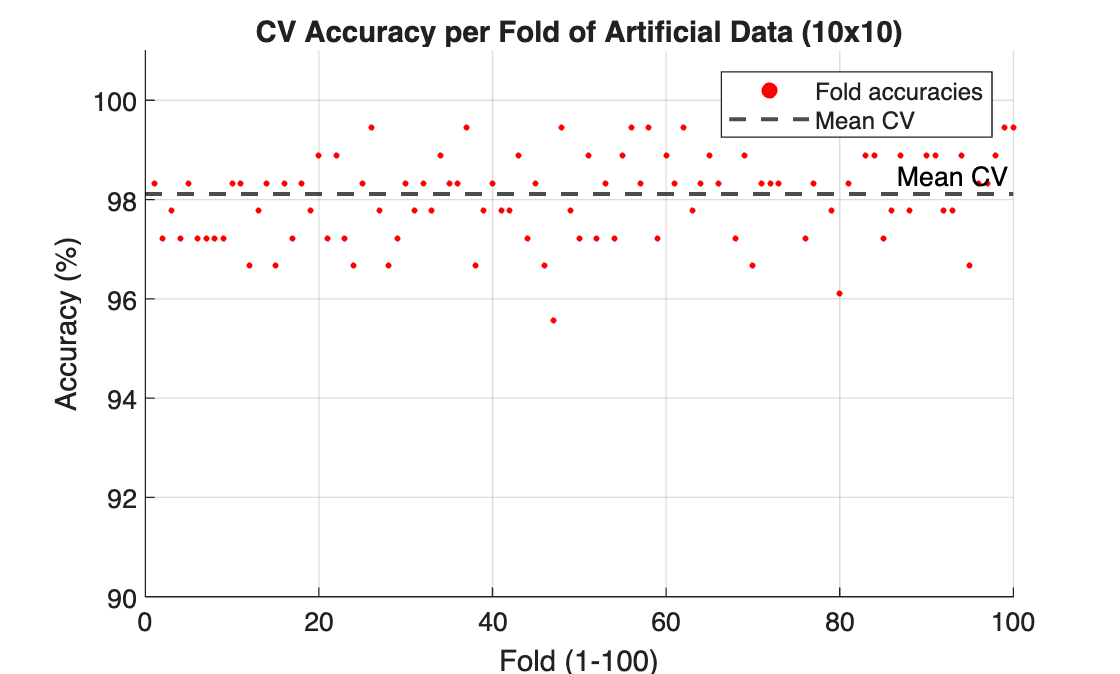

yline(mean_cv * 100, '--', 'LineWidth', 1.5, 'Color', 'black', 'Label', 'Mean CV');
title('CV Accuracy per Fold of Artificial Data (10x10)');
xlabel('Fold (1-100)');
ylabel('Accuracy (%)');
ylim([90 101]);
grid on;
legend('Fold accuracies', 'Mean CV');